hw04

task 1

clear all;
da1=load("hw\hw04\Exercise_4_Data.mat");
da2=load("hw\hw04\Exercise_4_Data_extra.mat");
[m,n]=size(da2.data);

task 2

%it's not enough at all to represent the dense sampling. we may need more
%than 100^100*2 data as for each dimension to represent the gaussian, 100
%points would be enough, so 100 dimensions would need 100^100, and for each
%class, then we would need to multiply 2.

task 3

training_d=da1.a(da1.Train_indx,:);
test_d=da1.a(da1.Test_indx,:);
label_tr=da1.classes(da1.Train_indx);
label_te=da1.classes(da1.Test_indx);

task 4

% mu_meas=mean(training_d);
% std_meas=std(training_d);
% training_nd=(training_d-mu_meas)./std_meas;
% test_nd=(test_d-mu_meas)./std_meas;

dim_keep=3;
mu_trda=mean(training_d);
mu_teda=mean(test_d);

Sca=cov(training_d-mu_trda);
[V,D]=eig(Sca);
eigV=diag(D);
[sort_v,sort_idx]=sort(eigV,'descend');
pca=V(:,sort_idx(1:dim_keep));
transformed_train=(training_d-mu_trda)*pca;
transformed_test=(test_d-mu_trda)*pca;

task 5

idx_t_0=find(label_te==0);
idx_t_1=find(label_te==1);
idx_tr_0=find(label_tr==0);
idx_tr_1=find(label_tr==1);

test_0=test_d(idx_t_0,:);
test_1=test_d(idx_t_1,:);
train_0=training_d(idx_tr_0,:);
train_1=training_d(idx_tr_1,:);

t_test_0=(test_0-mu_trda)*pca;
t_test_1=(test_1-mu_trda)*pca;
t_tr_0=transformed_train(idx_tr_0,:);
t_tr_1=transformed_train(idx_tr_1,:);

plot3(t_test_0(:,1),t_test_0(:,2),t_test_0(:,3),'o',t_test_1(:,1),t_test_1(:,2),t_test_1(:,3),'sq');
hold on
mu_1=mean(t_tr_1);
sig_1=cov(t_tr_1);
mu_0=mean(t_tr_0);
sig_0=cov(t_tr_0);
data_vol3D=vol3D([-1e9 1e9 -200 200 -200 200],200);

min_a = -1.0000e+09

max_a = 1.0000e+09

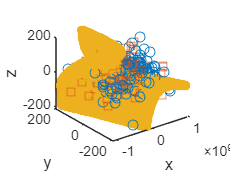

data_vol3D_t=data_vol3D.';

d1=dis(mu_1,sig_1,data_vol3D,1/2);
d0=dis(mu_0,sig_0,data_vol3D,1/2);
ind=[];
m=0;
for i=1:length(d1)
    if abs(d1(i)-d0(i))<=0.03
        ind(end+1)=i;
%         m=m+1;
    end 
end 
x_1=data_vol3D(ind,1);
y_1=data_vol3D(ind,2);
z_1=data_vol3D(ind,3);
% plot3([s1_x',s2_x',s3_x'],[s1_y',s2_y',s3_y'],[s1_z',s2_z',s3_z'],'.','MarkerSize',15)
% figure(1)
plot3 (x_1,y_1,z_1,'.','MarkerSize',15);
xlabel('x');
ylabel('y');
zlabel('z');

d1=dis(mu_1,sig_1,transformed_test,1/2);
d0=dis(mu_0,sig_0,transformed_test,1/2);
for i=1:length(transformed_test)
    if (d1(i)>d0(i) && label_te(i)==0)||(d0(i)>d1(i) && label_te(i)==1)
%         ind(end+1)=i;
        m=m+1;
    end 
end
accuracy_pca=(750-m)/750

accuracy_pca = 0.4920

%the accuracy is 49.2% which is low.

task 6

%pca is not a good approach for classification as it only take the variance
%of all the data into consideration. in other words, it just choose the
%coordinate axis that can most efficiently present the original data, which
%means less variation on the data. it contains no information of
%labels, so it's not good for classfication.

task 7

idx_tr_0=find(label_tr==0);
idx_tr_1=find(label_tr==1);
tr_0=training_d(idx_tr_0,:);
tr_1=training_d(idx_tr_1,:);
tr_mu_0=mean(tr_0);
tr_mu_1=mean(tr_1);
mu_trda;
N_0=height(tr_0);
N_1=height(tr_1);
Sw=N_0*cov(tr_0)+N_1*cov(tr_1);
Sb=N_0*((tr_mu_0-mu_trda)'*(tr_mu_0-mu_trda))+N_1*((tr_mu_1-mu_trda)'*(tr_mu_1-mu_trda));

[V,D]=eig(Sb,Sw);
eig=diag(D);
[sort_v,sort_idx]=sort(eig,'descend');
fld=V(:,sort_idx(1));
FLDtran_train=(training_d-mu_trda)*fld;
FLDtran_test=(test_d-mu_trda)*fld;
FLDt_train_0=(train_0-mu_trda)*fld;
FLDt_train_1=(train_1-mu_trda)*fld;
FLDt_test_0=(test_0-mu_trda)*fld;
FLDt_test_1=(test_1-mu_trda)*fld;
figure(2);
plot(FLDt_test_0(:,1),'o');
hold on
plot(FLDt_test_1(:,1),'sq');

task 8

fldmu_1=mean(FLDt_train_1);
fldsig_1=cov(FLDt_train_1);
fldmu_0=mean(FLDt_train_0);
fldsig_0=cov(FLDt_train_0);
fd1=dis(fldmu_1,fldsig_1,FLDtran_test,1/2);
fd0=dis(fldmu_0,fldsig_0,FLDtran_test,1/2);
m=0;
for i=1:length(transformed_test)
    if (fd1(i)>fd0(i) && label_te(i)==0)||(fd0(i)>fd1(i) && label_te(i)==1)
%         ind(end+1)=i;
        m=m+1;
    end 
end
accuracy_fld=(750-m)/750

accuracy_fld = 1

%it's perfectly classified all the data and the accurcy is 100%

task 9

%The projection direction of the dimensionality reduction vector of PCA is the 
% eigenvector of the largest eigenvalue of the covariance matrix. 
% The projection direction of Fisher's dimensionality reduction vector is the 
% eigenvector corresponding to the largest eigenvalue of the matrix Sw-1*Sb
% (Sb is between-class scatter matrices, Sw is within-class scatter matrices).
% PCA only has the ability to reduce the dimension, and its purpose is to reduce 
% the dimension of the data in the direction of the larger variance after projection,
%  without considering the classification. The difference is that Fisher can implement 
% classification at the same time. In other words, Fisher also considers the class 
% information after the projection while looking for the vector projection.

task 10

%no, i don't think it would improve any performance a lot as higher percentage of
%data only has effect on the choosing of coordinate that mostly represent
%the data and still contain no information of labels.

task 11

% Ex4_NNsetup(data,label,trInd,teInd)
ori=zeros(1000,2);
Tind_0=find(da1.classes==0);
Tind_1=find(da1.classes==1);
ori(Tind_0,1)=1;
ori(Tind_1,2)=1;
the_net=Ex4_NNsetup(da1.a,ori,da1.Train_indx,da1.Test_indx);
%

task 12

y=the_net(test_d');
% label=da1.classes;
m=0;
for i=1:750
    if (y(1,i)>y(2,i) && label_te(i)==1)||(y(1,i)<y(2,i) && label_te(i)==0)
        m=m+1;
    end
end
accuracy_nn=(750-m)/750

accuracy_nn = 0.6173

%the accuracy is about 68%, which is relatively higher tahn pca based
%classsification and lower tham FIsher based classification. The
%information gained from nn is less than the PCA and FLD
%gained, as it cannot gain the distribution information. FLD can use more
%information as it will take the lables into consideration for dimension
%reduction. this will still hold for non-linearly seperable problem because
%for FLD, the projection can still project the non-linearly seperable data
%to the new axises to make it linearly seperable.
%%Fisher's approach is to map multidimensional features into one dimension. 
% The importance of each dimension in the mapping process is different. 
% After the linear mapping of WTX+b, a scalar is obtained, and then this scalar 
% is directly used for judgment. A neural network is actually solving a high-dimensional 
% system of equations. In each layer of the neural network, the data obtained 
% from the previous layer undergoes linear mapping of WTx+b, and then undergoes 
% nonlinear transformation through the activation function. Nest σ(WTx+b) 
% many times, and finally get a predicted value y*. The neural network 
% can divide the irregular decision-making surface into enough small segments, 
% and by continuously adjusting the internal parameters of the network, 
% it can continuously approach the real decision-making surface. 
% Due to the local optimal solution problem, its performance depends on the 
% random initialization of parameters and the choice of hyperparameters. And this would 
% continue to hold for non-linearly separable problem domains.

task 13

the_i=sort_idx(1);
ind_13=ones(1,100);
ind_13(the_i)=0;
new_test_d=test_d(:,logical(ind_13));

ori=zeros(1000,2);  
Tind_0=find(da1.classes==0);
Tind_1=find(da1.classes==1);
ori(Tind_0,1)=1;
ori(Tind_1,2)=1;
nine_data=da1.a(:,logical(ind_13));
the_net_13=Ex4_NNsetup(nine_data,ori,da1.Train_indx,da1.Test_indx);
y_13=the_net_13(new_test_d');
m=0;
for i=1:750
    if (y(1,i)>y(2,i) && label_te(i)==1)||(y(1,i)<y(2,i) && label_te(i)==0)
        m=m+1;
    end
end
accuracy_nn_13=(750-m)/750

accuracy_nn_13 = 0.6173

%the classification accuracy is about 68%. the overall classification
%distribution should still be about 50% as the NN will get into the
%overfitting problems and so that the accuracy will be generally 50% which
%is simply similar to the random classification.



task 14

%a good classifer can be trained with the training data set which is dense
%sampling with informative features.However, it is not always easy to get
%the informative features. for example, when we try to research on the
%causes of diabetes, the features are exactly what we are studying on, in
%other words, we have no idea about wheter they are informative or not.

discriminant function

function D=dis(u,c,x,pk)

t1=x*(-1/2*inv(c)); %100*3
t2=dot(t1,x,2); %100*1
tA=t2'; %1*100
tB=(inv(c)*u')'*x';
t3=-1/2*u*inv(c)*u'-1/2*log(det(c))+log(pk);
len=length(x);
tC=ones(1,len)*t3;
D=tA+tB+tC; %1*100

end

vol3D

function V = vol3D(Vaxis,Num)
% VOL3D Build 3D volume of regular grid points.
%   V = vol3D(Vaxis,Num) returns a (Num^3)-by-3 matrix containing the
%   coordinates for regularily spaced points inside of a rectangular
%   volume. The points are listed row-wise in V: the x-coordinates of
%   all points are V(:,1). Similarily, the y-coordinates are V(:,2) and
%   the z-coordinates are V(:,3).
%
%   Vaxis is a 6-element vector which defines the rectangular volume. Each
%   pair of elements define the minimum and maximum extent of the volume
%   along an axis. For example, a 4x6x8 volume centred on the origin would
%   be defined with Vaxis = [-2 2 -3 3 -4 4]
%   
%   Num is a scalar. It is the number of points to generate along any axis.
%   The total number of points generated is Num^3.

NV = Num;
% Vaxis = [-2 2 -3 3 -4 4];
if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis]
end

min_a = Vaxis(1)
max_a = Vaxis(2)
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end


function for net in hw04

%Template for setting up and training a pattern classification neural net
%which:
%1) performs no normalization or other preprocessing of the input
%2) uses predefined test/va/train sets according to indices
%
%-- A. Dimopoulos, June 2022

function NN=Ex4_NNsetup(data,label,trInd,teInd)
%all Data and labels. -->DEFINE THESE<--
Dall=data';
Tall=label';

%set indices. -->DEFINE THESE<--
%training indices
TRAIN_IND = trInd;
%validation indices
% pos=randi(length(teInd)/2);
VAL_IND = teInd(1:length(teInd)/2);
%testing indices
TEST_IND = teInd(length(teInd)/2+1:length(teInd));

%declare a classification network with default number of hidden units
n = patternnet;
%ensure that no data normalization or other preprocessing is performed
n.inputs{1}.processFcns = {};
%assign train/val/test sets by index
n.divideFcn = 'divideind';
n.divideParam.trainInd = TRAIN_IND;
n.divideParam.valInd = VAL_IND;
n.divideParam.testInd = TEST_IND;
%configure input and output sizes
n = configure(n,Dall,Tall);
%initialize the network weights
n = init(n);
%train the network
[n,train_record] = train(n,Dall,Tall);
NN=n;
end